# HCTHX notebook 1

HNXJ@github

Jan30-2025

clear;clc;close all;

cd('D:\Electrophysiology\Matdelane\');
addpath(genpath('matnwb'));
addpath(genpath('matdelane'));
addpath(genpath('flipv2'));
addpath(genpath('eeglab_current'));

generateCore();

addpath('fieldtrip');ft_defaults;

-------------------------------------------------------------------------------------------
FieldTrip is developed by members and collaborators of the Donders Institute for Brain,
Cognition and Behaviour at Radboud University, Nijmegen, the Netherlands.

                          --------------------------
                        /                            \
                     ------------------------------------
                    /                                    \
          -------------------------------------------------
         /                            /\/\/\/\/\ 
         ---------------------------------------------------
                  |        F  i  e  l  d  T  r  i  p       |
                  ------------------------------------------
                   \                                      /
                     ------------------------------------
                          \            /
                            ----------

Please cite the FieldTrip re

a1 = load('-mat', "Lab Assignment\OddballData\OddballPilotData_UM1331\UM1331_Oddball1.set");
a2 = load('-mat', "Lab Assignment\OddballData\OddballPilotData_UM1331\UM1331_Oddball2.set");

EEG = a2;
ntrials= size(EEG.event,2);
all_event_latencies = zeros(ntrials,1);
all_event_types = zeros(ntrials,1);
for t = 1:ntrials

    all_event_latencies(t) = EEG.event(t).latency;
    all_event_types(t) = EEG.event(t).type;
end

%nchan = size(EEG.data,1);
nchan = 134;
epoched_data = zeros(ntrials, nchan, 2501);
for t = 1:ntrials
    epoched_data(t,:,:) = EEG.data(1:nchan,ceil(all_event_latencies(t))-500:ceil(all_event_latencies(t))+2000);
end

% figure; imagesc(squeeze(mean(epoched_data)))

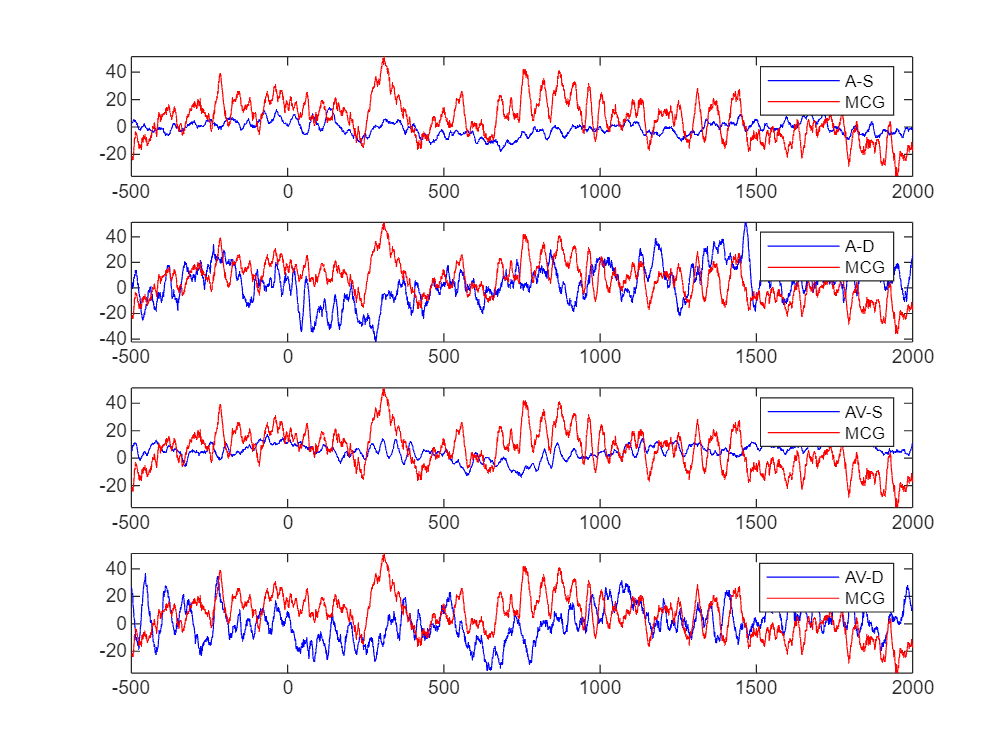

x = cell(1);
x{1} = find(all_event_types == 201);
x{2} = find(all_event_types == 202);
x{3} = find(all_event_types == 203);
x{4} = find(all_event_types == 204);
x{5} = find(all_event_types == 205);

%X01-X05 are: {'A-STD','A-DEV','AV-STD','AV-DEV','MCGURK'};
xlabel = ["A-S", "A-D", "AV-S", "AV-D", "MCG"];
figure; 

for i = 1:4

    subplot(4, 1, i);
    plot(-500:2000, squeeze(mean(epoched_data(x{i},95,:))), 'b', "DisplayName", xlabel(i));
    hold on;
    plot(-500:2000, squeeze(mean(epoched_data(x{5},95,:))), 'r', "DisplayName", xlabel(5));
    % ylim([-130 50]);
    legend;

end

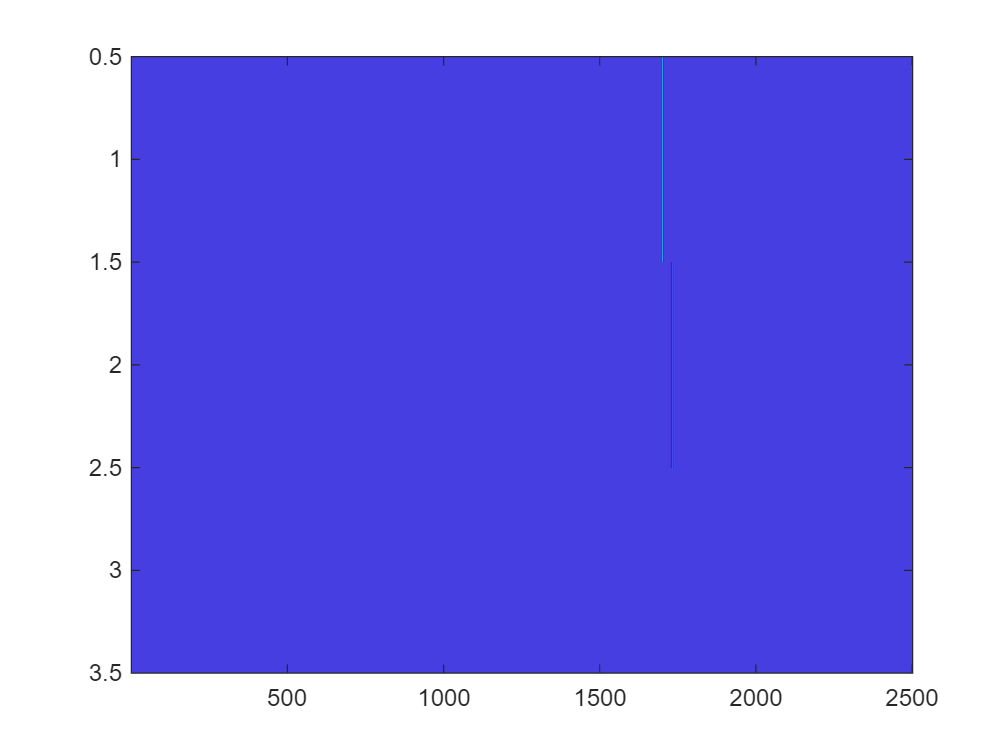

figure;
imagesc(squeeze(epoched_data(x{5},95,:)));

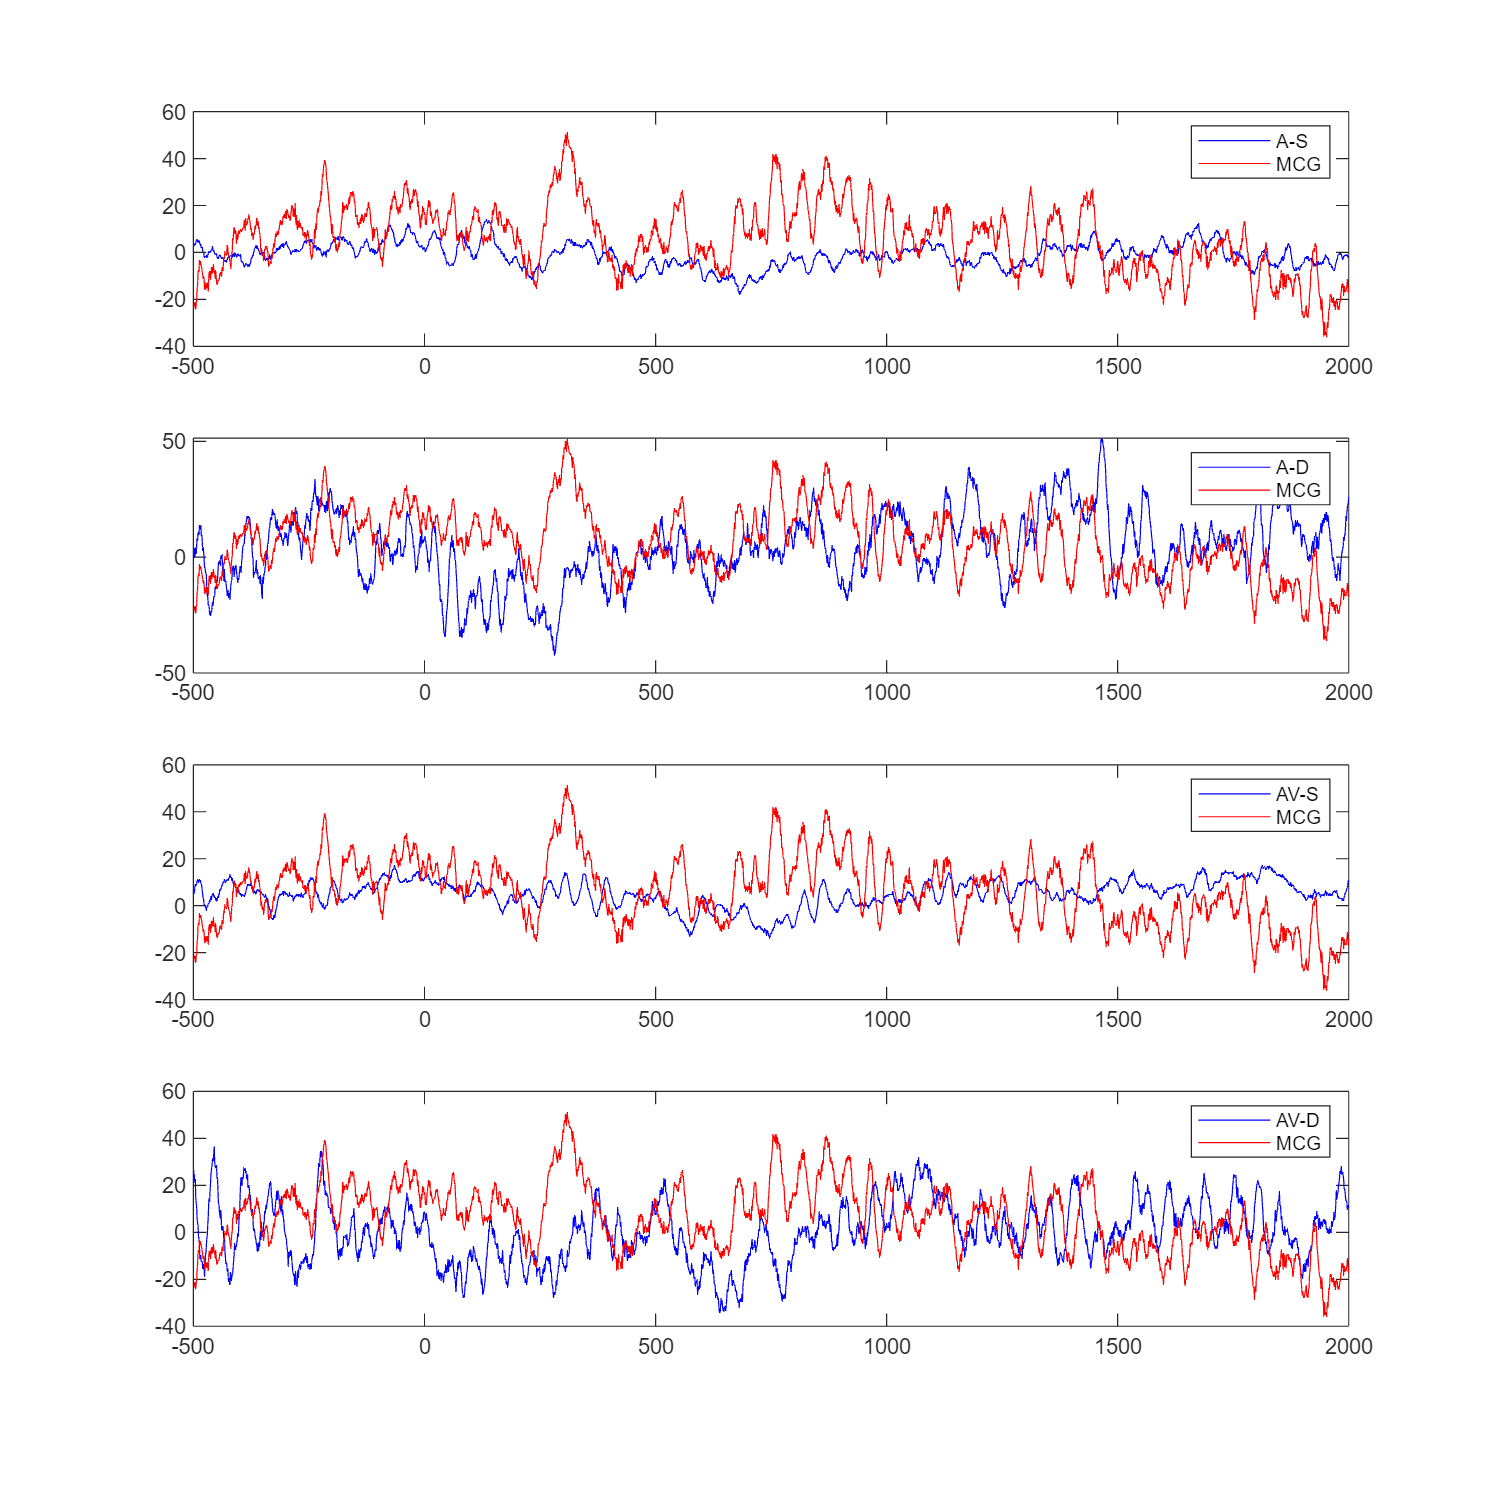

x = cell(1);
x{1} = find(all_event_types == 201);
x{2} = find(all_event_types == 202);
x{3} = find(all_event_types == 203);
x{4} = find(all_event_types == 204);
x{5} = find(all_event_types == 205);
x1 = cell(1);

for i = 1:5

    x1{i} = epoched_data(x{i}, 1:130, :);

end

figure("Position", [0 0 1000 1000]);

for i = 1:4

    subplot(4, 1, i);
    plot(-500:2000, squeeze(mean(x1{i}(:, 95, :), 1)), 'b', "DisplayName", xlabel(i));
    hold on;
    plot(-500:2000, squeeze(mean(x1{5}(:, 95, :), 1)), 'r', "DisplayName", xlabel(5));
    % ylim([-130 50]);
    legend;

end

% for i = 1:5
% 
%     for ij = 1:size(x1{i}, 1)
% 
%         for ik = 1:size(x1{i}, 2)
% 
%             x1{i}(ij, ik, :) = conv(squeeze(x1{i}(ij, ik, :)), [-1, +1], "same");
% 
%         end
% 
%     end
% 
% end

c1 = cell(1);

for i = 1:4

    c1{i} = corr(squeeze(mean(x1{i}, 1))', squeeze(mean(x1{5}, 1))', "Type","Spearman");

end

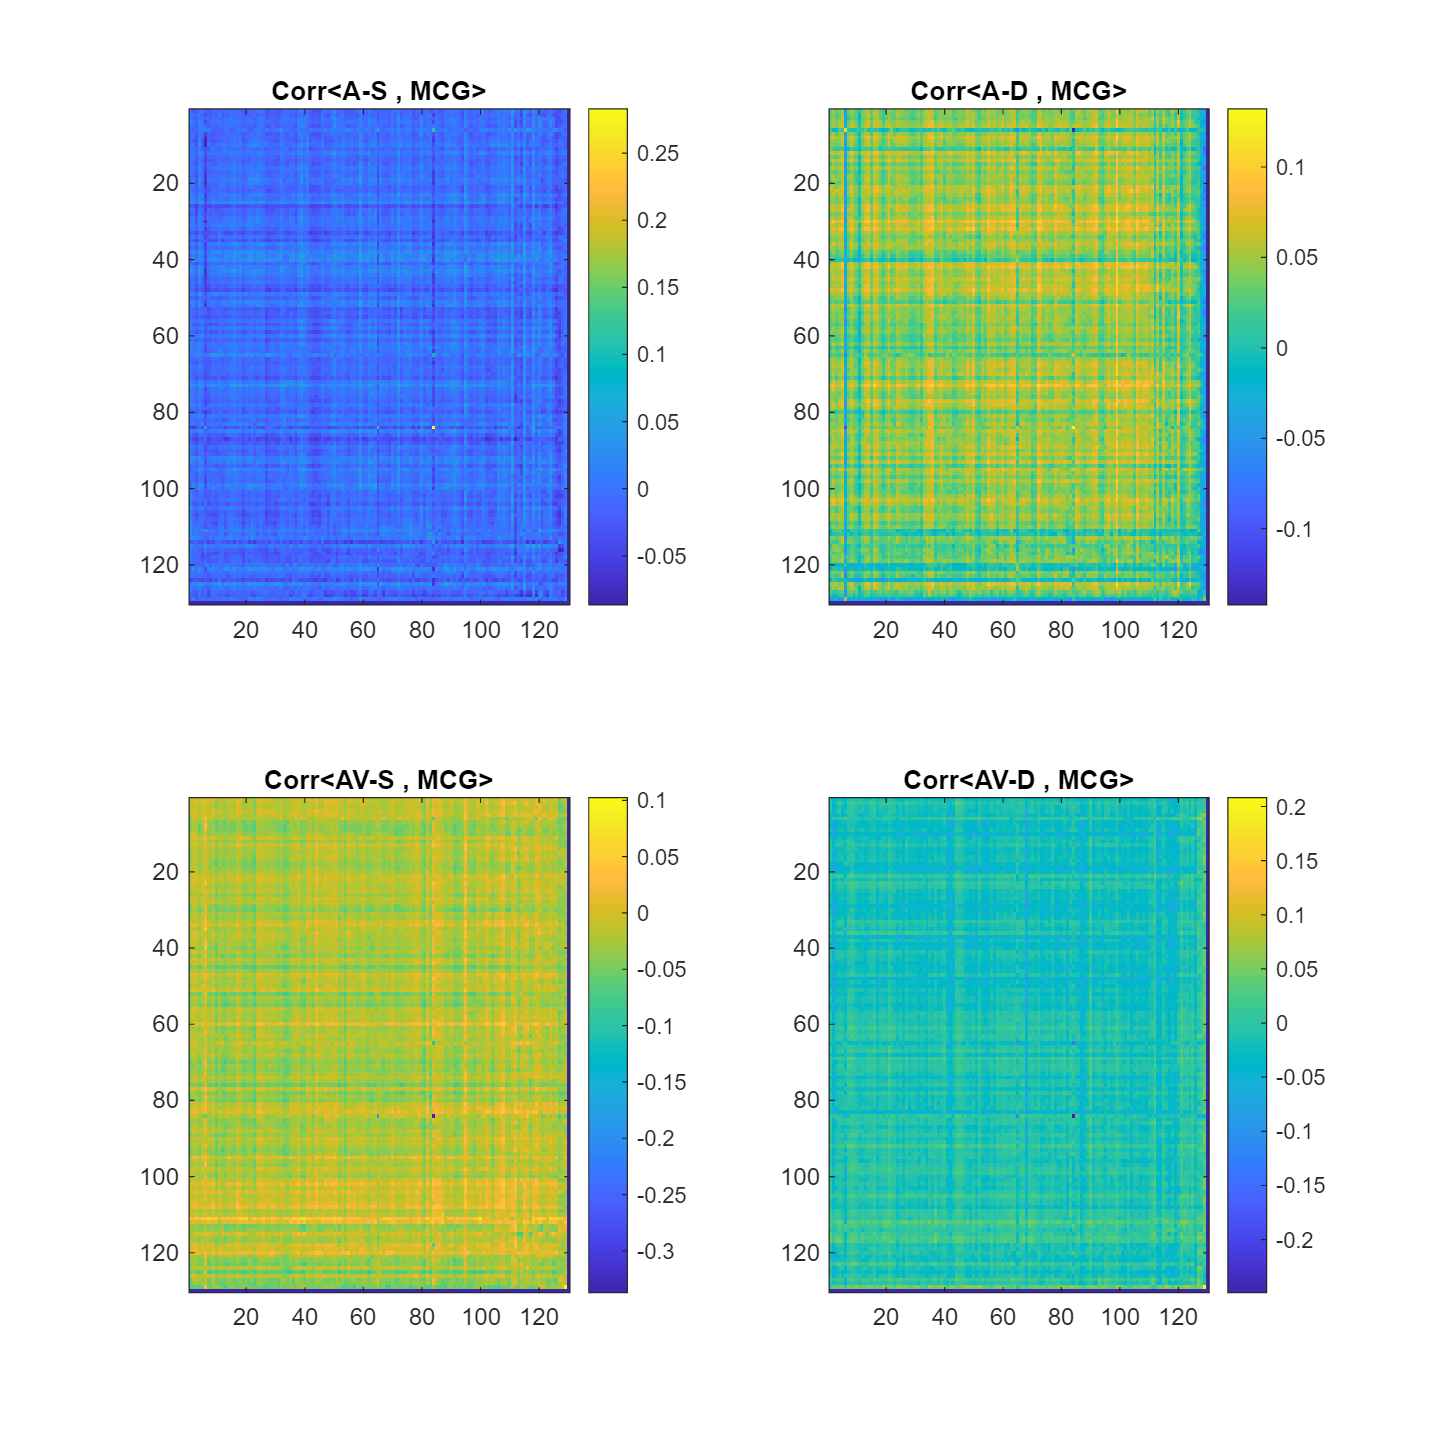

figure("Position", [0 0 1000 1000]);

for i = 1:4

    subplot(2, 2, i);
    imagesc(c1{i});
    title("Corr<" + xlabel{i} + " , " + xlabel{5} + ">");
    colorbar;

end

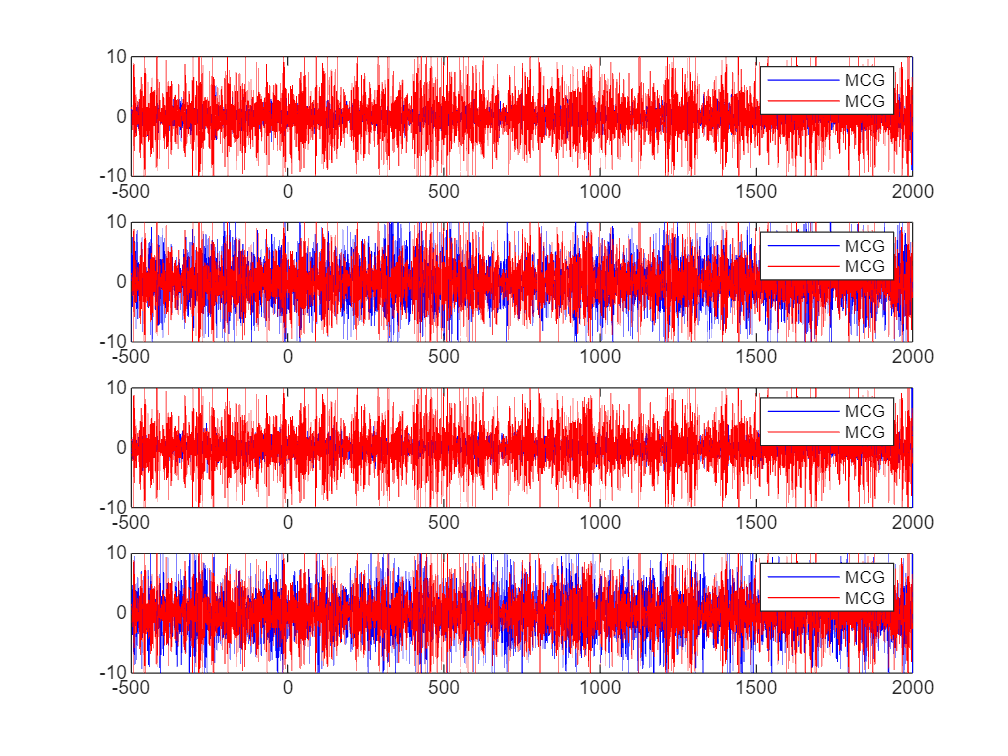

figure;

for i = 1:4

    subplot(4, 1, i);
    plot(-500:2000, squeeze(mean(x1{i}(:, 101, :), 1)), 'b', "DisplayName", xlabel(5));
    hold on;
    plot(-500:2000, squeeze(mean(x1{5}(:, 101, :), 1)), 'r', "DisplayName", xlabel(5));
    ylim([-10 10]);
    legend;

end

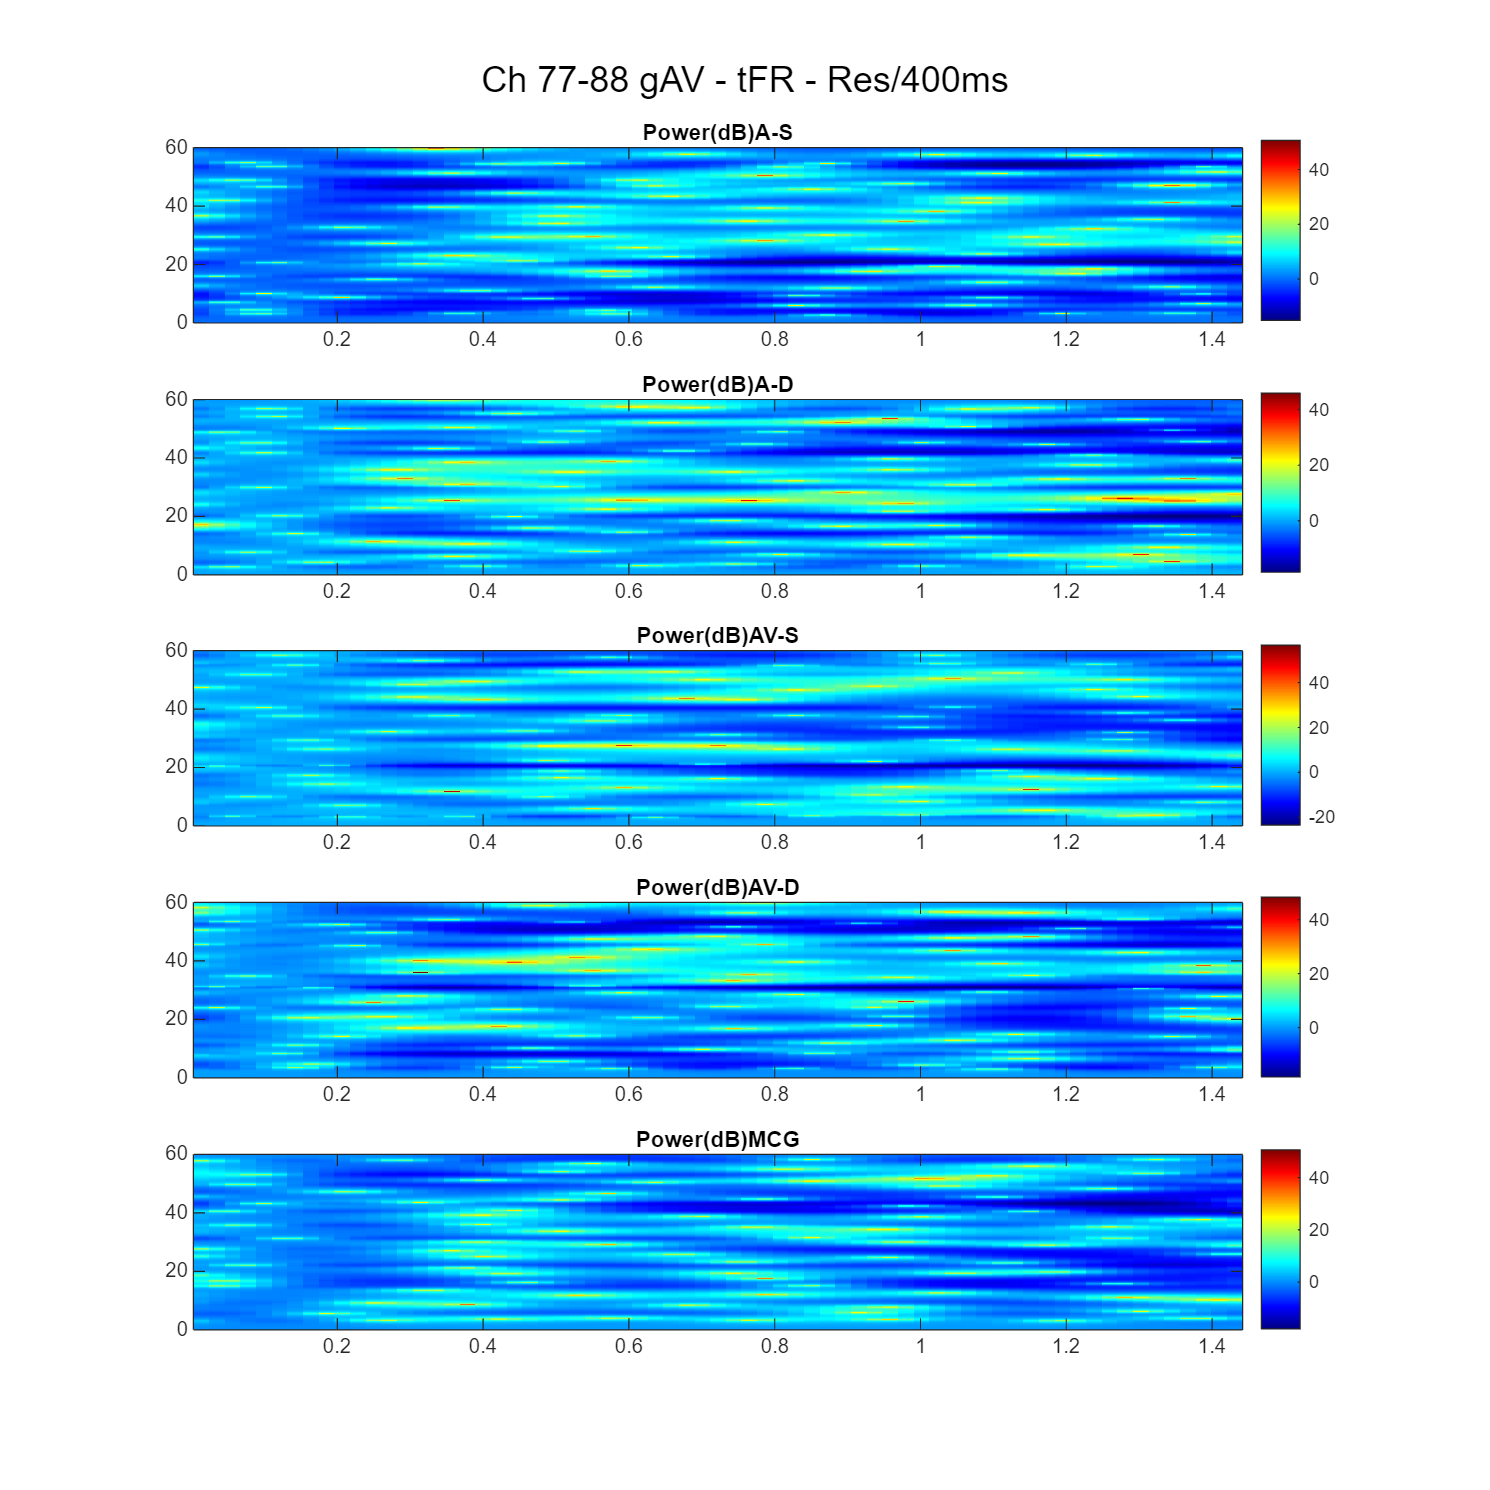

figure("Position", [0 0 1000 1000]);
chid = 77:88;

for i = 1:5

    [tfr1, f, t] = pspectrum(squeeze(mean(x1{i}(1, chid, :), 2)), 1024, ...
        "spectrogram", "FrequencyResolution", 2.5, "OverlapPercent", 98, "FrequencyLimits", [0 60]);

    bsl = mean(tfr1(:, 1:10), 2);

    for ij = 1:size(tfr1, 2)

        tfr1(:, ij) = tfr1(:, ij)./bsl;

    end

    subplot(5, 1, i);
    imagesc(-10*log10(tfr1), "XData", t-0.5, "YData", f(end:-1:1));
    xline(0, "LineWidth", 1.0);
    
    set(gca,'YDir','normal');
    colorbar;colormap("jet");
    title("Power(dB)" + xlabel(i));
    % hold on;
    % imagesc(tfr2, "XData", t, "YData", f);

end
sgtitle("Ch 77-88 gAV - tFR - Res/400ms");